# Transfer Function Estimation

`Vehicle Braking Simulations`

`Brian Lesko, Graduate Researcher and Teaching Associate, Masters of mechanical engineering student `

`Check out the Equations of motion, Matlab Script, Simulink, and more at my github repository`

[`https://github.com/BrianLesko/LongitudinalVehicleDynamics`](https://github.com/BrianLesko/LongitudinalVehicleDynamics)

`Longitudinal Vehicle Modeling Series`

`7/27/23`

` Ohio State University`

Loading in the accelerations simulation data 

load('vehicleCellsBrake.mat')

## Simulated Velocity Torque Transfer Function 

From the simulation data, we can approximate a transfer function between Velocity and Motor torque by dividing the velocity at each timestep by the brake torque used. 

Absolute values! 

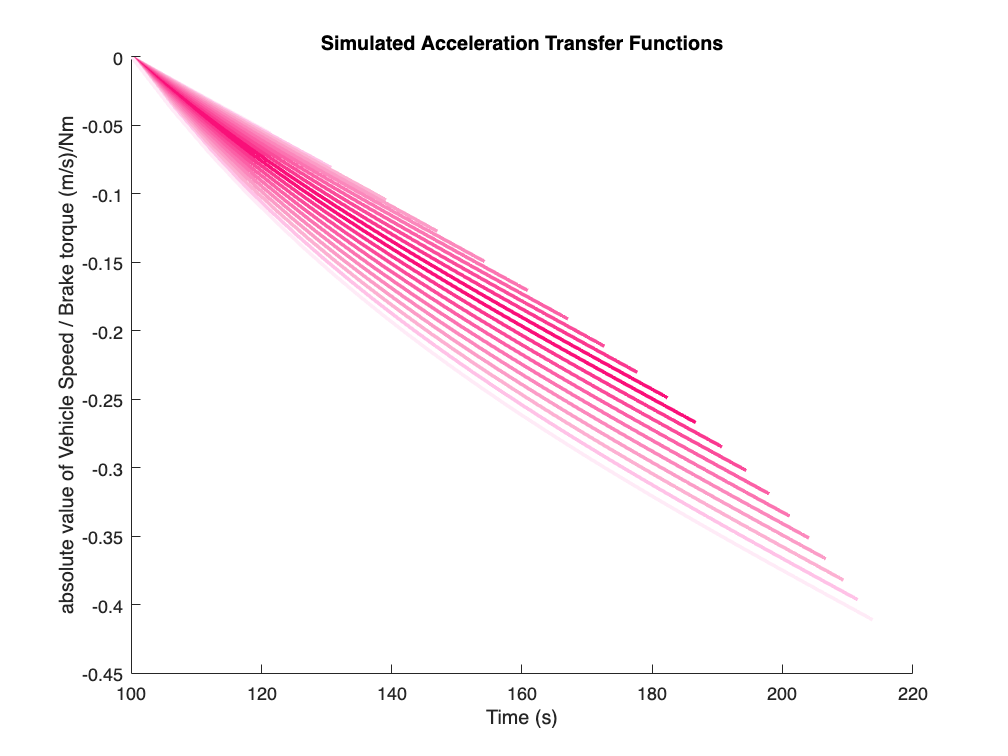

legendInfo = aniSimCells2(vehicleCellsBrake);

# `Functions `

function plotFromCells_SimulatedTF(simCells)
n = length(simCells);
colors = getColors(); colors2 = getColors2();
    for i = 1:1:n
        % fetching the variables 
        time = simCells{i}.time; V = simCells{i}.V; Tm = simCells{i}.Tm(1); Tb = simCells{i}.Tb(1);
        color = colors(i); color2 = colors2(i);
        plot(time,V./(Tm-Tb),'r','linewidth',2,'Color',color);
        legendInfo{i} = sprintf('Tm-Tb', num2str(Tm-Tb));
    end 
end 
function colors = getColors()
    a = "#0A0A0A"; % night
    %b = "#131315"; % night 
    %c = "#1D1D20"; % eerie black
    d = "#27272B"; % raisin black
    %e = "#303036"; % jet
    %f = "#3A3A41"; % onyx
    g = "#43434C"; % onyx
    %h = "#565661"; % davy"s gray
    %i = "#60606C"; % dim gray
    j = "#696977"; % dim gray
    %k = "#737382"; % slate gray
    l = "#7D7D8C"; % taupe gray
    m = "#93939F"; % cool gray
    n = "#A9A9B2"; % french gray
    o = "#BEBEC5"; % french gray
    p = "#D4D4D9"; % platinum
    q = "#EAEAEC"; % anti-flash white

    colors = [q,p,o,n,m,l,j,g,d,a,a,d,g,j,l,m,n,o,p,q]; 
end     

function colors = getColors2()
    a = "#F91079"; 
    d = "#FA388F"; 
    g = "#FA4C9A"; 
    j = "#FB60A6"; 
    l = "#FB74B1"; 
    m = "#FB88BC"; 
    n = "#FB9DC7"; 
    o = "#FCB1D2"; 
    p = "#FFC2E7"; 
    q = "#FFEBF7";

    colors = [q,p,o,n,m,l,j,g,d,a,a,d,g,j,l,m,n,o,p,q]; 
end  

Animation functions 

function legendInfo = aniSimCells2(simCells)
    n = length(simCells(1,:));
    colors = getColors();
    finalColors = getColors2();  % Get the final colors from getColors2()

    figure;
    hold on;

    % Pre-plotting to get the axes limits
    for i = 1:1:n
        time = simCells{i}.time;
        dV = simCells{i}.V(1) - simCells{i}.V;
        TFy = dV/(simCells{i}.Tm-simCells{i}.Tb);
        plot(time,TFy,'Color',"#FFFFFF");
    end

    % Get the current axes limits
    ax = gca;
    xl = ax.XLim;
    yl = ax.YLim;

    % Clear the axes
    cla;

    title('Simulated Braking Transfer Functions'), xlabel('Time (s)'), ylabel(' Change in Vehicle Speed / Brake torque (m/s)/Nm')

    % Initialize animated lines
    h = gobjects(1, n);
    for i = 1:1:n
        color = colors(i);
        h(i) = animatedline('Color', color, 'LineWidth', 2);
        ax = gca;
        ax.XLim = xl;
        ax.YLim = yl;
    end

    % Add points to all lines, updating the plot as we go
    for j = 1:length(simCells{1}.time)
        for i = 1:1:n
            time = simCells{i}.time;
            dV = simCells{i}.V(1) - simCells{i}.V;
            TFy = dV/(simCells{i}.Tm-simCells{i}.Tb);
            addpoints(h(i), time(j), TFy(j));
            
            % If the current x-value is around 300, change the color of the line
            if TFy(j) <= 0.002
                h(i).Color = finalColors(i);
            end
        end
        if mod(j,1) == 0 % update the plot every n points
            drawnow;
        end
    end

    % Add legend information
    for i = 1:1:n
        Tb = simCells{i}.Tb(1); % (1) because the motor torque is constant
        legendInfo{i} = sprintf('Brake Torque = %s', num2str(Tb));
    end 
    hold off;
end